# Working with Gaussians

## Estimating unobserved data

In this live script, we will be working with temperature data in Boston. We will use the concepts explored in this section to create estimates of unobserved data using Gaussian processes. 

## The Data (Avalilable in https://www.usclimatedata.com/)

Initially, lets load the data available for this example. We have two data sets

- Weather information in Boston in the forms of averages from 1981 to 2010. We are provided with average high and low temperature precipitation and inches of snow for every day of the year.

- Weather information in Boston in 2019. We are provided with average high and low temperature precipitation and inches of snow for every day of the year.

For simplicity we are going to work with the temperature information only.

The provided file 'data.mat' consis of 4 columns and 365 rows. Each row indicates a consecutuve day of the year. 

- Column 1 is the highest recorded temperature in Boston in 2019 in a particular day.

- Column 2 is the lowest recorded temperature in Boston in 2019 in a particular day.

- Column 3 is the average of the highest recorded temperatures in Boston from 1981 to 2010 in a particular day.

- Column 4 is the average of the lowest recorded temperature in Boston from 1981 to 2010 in a particular day.

Load the average data

d = load('data.mat');
data = d.data;

Let's see how the data looks like

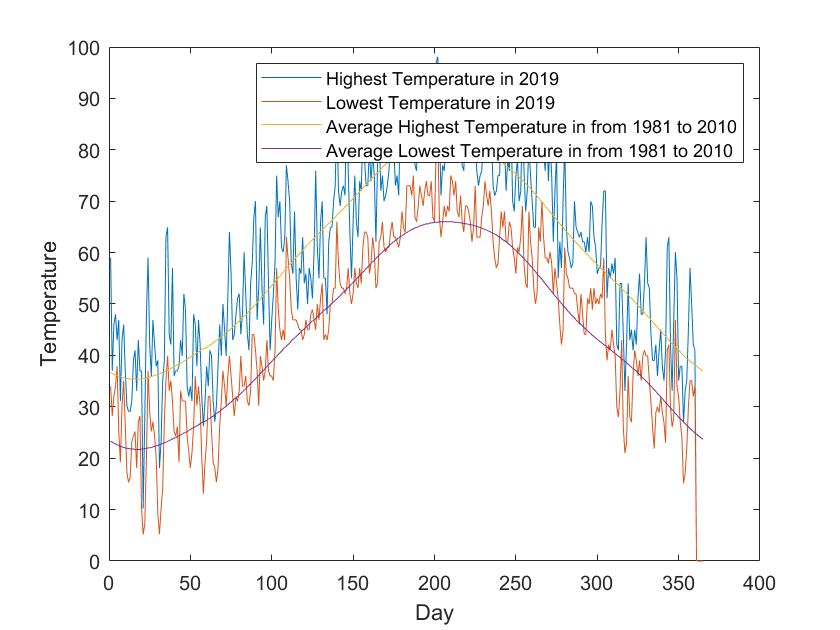

x = [1:365];              % The day index
figure;
plot(x,data);
xlabel('Day');
ylabel('Temperature');
legend('Highest Temperature in 2019','Lowest Temperature in 2019',['Average ' ...
    'Highest Temperature in from 1981 to 2010 '],['Average Lowest Temperature ' ...
    'in from 1981 to 2010 ']);

#### Note: Temperature information is missing for the last 5 days of 2019. Entries have been filled with zeros, but this does not mean the temperature is zero.

## The Model

For simplicity we are going to work with the highest temperature of the day variable. The process for the lowest temperature, or the amout of snow or precipitaion follow a similar principle.

We have model the temperature for each day as a Gaussian random variable. We have will use the average data infomation as surrogate for the mean of the random variables.  We will consider the temperature data in 2019 as the observations of those random variables.

For instructional purposes lets assume we only have measurements in 2019 once every 4 days. Thus we define

${\mathit{\mathbf{X}}}_1 :$ Multivariate Gaussian random variable. Temperature in Boston for the days we do not have observations: Day 2, Day 3, Day 4 Day 6, ....

${\mathit{\mathbf{X}}}_2 :$ Multivariate Gaussian random varibale. Temperature in Boston for the days we have observations. Day 1, Day 5, Day 9.......

$x_2 :$ Observations of ${\mathit{\mathbf{X}}}_2$

$\mu_1 :$ Mean of ${\mathit{\mathbf{X}}}_1$: Column 3 in the data, index 2, 3, 4, 6, 7, 8....

$\mu_2 :$ Mean of ${\mathit{\mathbf{X}}}_2$: Column 3 in the data index 1, 5, 9, .

#### The kernel function for the Covariance Matrix

Here, we should make a choice for the kernel function that is going to model the covariance matrix. Lets pick


$$k\left(z_1 ,z_2 \right)=a*\exp \left(-\frac{\left\|z_1 -z_2 {\left\|\right.}^2 \right.}{2\ell^2 }\right)\ldotp$$


There are many options for the kernel function, the selection of a "good" kernel function is an optimization problem itself. In the homework yyou will have to pick one. It will be sufficient to provide some reasonable justification for the selection.

For the selected kernel function, we can identify the set of parameters $\theta =\left(a,\ell \right)$. We will devise a way to find "good" values for these parameters.

Let's see how the parameters affect the shape of the kernel function.

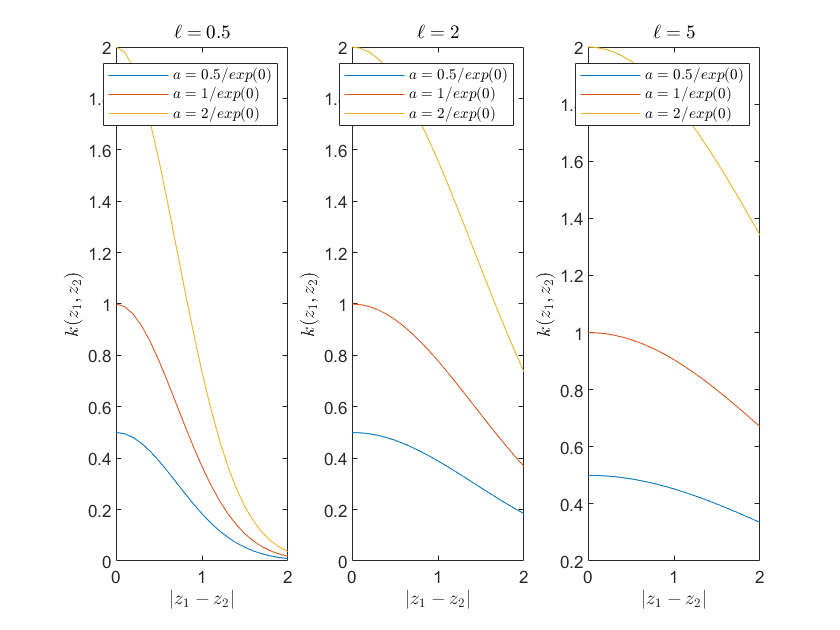

x = [0:0.1:2];
a = [0.5/exp(0) 1/exp(0) 2/exp(0)];
ell = [0.5 2 5];
y1 = [0.5/exp(0) 1/exp(0) 2/exp(0)]'.*exp(-x.^2/(2*ell(1)));
y2 = [0.5/exp(0) 1/exp(0) 2/exp(0)]'.*exp(-x.^2/(2*ell(2)));
y3 = [0.5/exp(0) 1/exp(0) 2/exp(0)]'.*exp(-x.^2/(2*ell(3)));


subplot(131)
plot(x,y1)
xlabel('$|z_1 - z_2|$', 'interpreter', 'latex')
ylabel('$k(z_1,z_2)$', 'interpreter', 'latex')
legend('$a=0.5/exp(0)$','$a=1/exp(0)$','$a=2/exp(0)$', 'interpreter', 'latex')
title('$\ell=0.5$', 'interpreter', 'latex')
subplot(132)
plot(x,y2)
xlabel('$|z_1 - z_2|$', 'interpreter', 'latex')
ylabel('$k(z_1,z_2)$', 'interpreter', 'latex')
legend('$a=0.5/exp(0)$','$a=1/exp(0)$','$a=2/exp(0)$', 'interpreter', 'latex')
title('$\ell=2$', 'interpreter', 'latex')
subplot(133)
plot(x,y3)
xlabel('$|z_1 - z_2|$', 'interpreter', 'latex')
ylabel('$k(z_1,z_2)$', 'interpreter', 'latex')
legend('$a=0.5/exp(0)$','$a=1/exp(0)$','$a=2/exp(0)$', 'interpreter', 'latex')
title('$\ell=5$', 'interpreter', 'latex')

The selected kernel function depends on a ''distance" between the random variables at hand. In the notes, and early in this recitation we talked about the example of two cities, and the kernel function depends on the distance between the physical location of the two cities. In this case, each random variable represents the temeperature on a day, so the distance between two random variables can be understood as the distance between the "location" between these random variables. Of couse, this distance is in the time variable. For example we can consider the distance between two of these random variables as 1, represnting a day. At this moment we do not care too much about the units, as the appropriate value for $\ell$ will incorporate the normalizing constant.

#### Partition the observed data for cross validation

We will use the described cross validaton process. Where we are going to partition the available observations $x_2$ into $\kappa$partitions. For simplicity lets initially pick $\kappa =2,$ that is, we partition  $x_2$ into two groups.

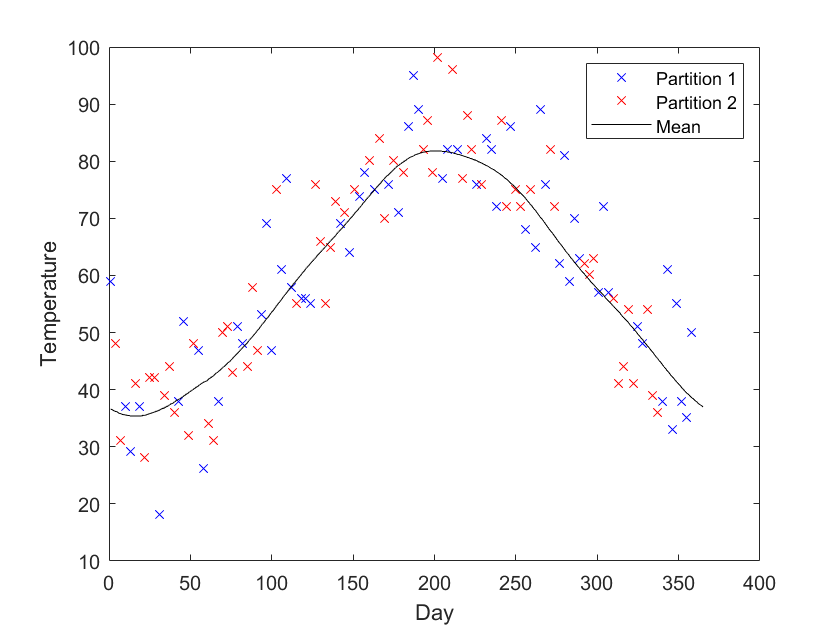

ind_x2 = [1:3:360];                % Find the indices of the measured data
perm = randperm(size(ind_x2,2));   % Create a random permulation of the incides
                                            % Goes to 360 because the last
                                            % 5 days are missing
p1 = sort(perm([1:size(perm,2)/2]));
p2 = sort(perm([size(perm,2)/2+1:end]));

k1_x2 = ind_x2(p1);           % Indices of partition 1
k2_x2 = ind_x2(p2);       % Indices of partition 2


x = [1:365];              % The day index
figure;
plot(k1_x2,data(k1_x2,1),'xb');
hold on
plot(k2_x2,data(k2_x2,1),'xr');
plot(data(:,3),'k');
xlabel('Day');
ylabel('Temperature');
legend('Partition 1','Partition 2','Mean');
hold off

### The Conditional Distribution of Partition 1 given Partition 2

Here we are going to build a function that computes the conditional mean and variance of the random variables in Partition 1 given the data in Partition 2.

% Set some value to the parameter of the function
theta(1) =9.7;
theta(2) =0.4;
theta(3) =0.97;
       

%% Compute the Covariance Matrix using the Kernel function
covs = repmat([1:365],365,1) - repmat([1:365]',1,365);

sigma = theta(1)*exp( -covs.^2 / theta(2)^2);

Now, we separate each of the components of the Covariance matrix


$$\Sigma =\left\lbrack \begin{array}{cc}
\Sigma_{11}  & \Sigma_{12} \\
\Sigma_{21}  & \Sigma_{22} 
\end{array}\right\rbrack$$


$\Sigma_{11} :$Covariance of the Partition 1 entries

$\Sigma_{12} :$Cross Covariance of the Partition 1 and 2 entries

$\Sigma_{22} :$Covariance of the Partition 2 entries

sigma_11 = sigma(k1_x2,k1_x2);
sigma_12 = sigma(k1_x2,k2_x2);
sigma_21 = sigma(k2_x2,k1_x2);
sigma_22 = sigma(k2_x2,k2_x2);

mu_1 = data(k1_x2,3);
mu_2 = data(k2_x2,3);


It is time to compute the conditional mean and conditional variance


$$\mathbf{{\mu}_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}=x_2^{-i}}   = \mathbf{{\mu}_2^i + \Sigma_{X_2^i,X_2^{-i}}\Sigma_{\mathbf{X}_2^{-i},\mathbf{X}_2^{-i}}^{-1}(\mathbf{x}_2^{-i}-\mathbf{{\mu}_2^{-i})  \\
\Sigma_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}=\mathbf{x}_2^{-i}}  = \Sigma_{\mathbf{X}_2^{i},\mathbf{X}_2^{i}} - \Sigma_{\mathbf{X}_2^{i},\mathbf{X}_2^{-i}}\Sigma_{\mathbf{X}_2^{-i},\mathbf{X}_2^{-i}}^{-1}\Sigma_{\mathbf{X}_2^{-i},\mathbf{X}_2^{i}}.$$


Recall that we denote $\mu^{-i}$as the information of all the data minos the partition $i$. Thus, for $i=1,$ the term $\mathbf{{\mu}_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}=x_2^{-i}} $ indicates the mean of the Partition 1 conditioned on the information from Partition 2.

mu_1_2 = mu_1 + sigma_12*((sigma_22+theta(3)*eye(size(mu_2,1)))\(data(k2_x2,1)-mu_2));
mu_2_2 = mu_2 + sigma_22*((sigma_22+theta(3)*eye(size(mu_2,1)))\(data(k2_x2,1)-mu_2));
sigma_1_2 = sigma_11 - sigma_12*((sigma_22+theta(3)*eye(size(mu_2,1)))\sigma_12');
sigma_2_2 = sigma_22 - sigma_22*((sigma_22+theta(3)*eye(size(mu_2,1)))\sigma_22');


We have computed the conditional distributions of the Partition 1 given Partition 2. Let's see how this looks like

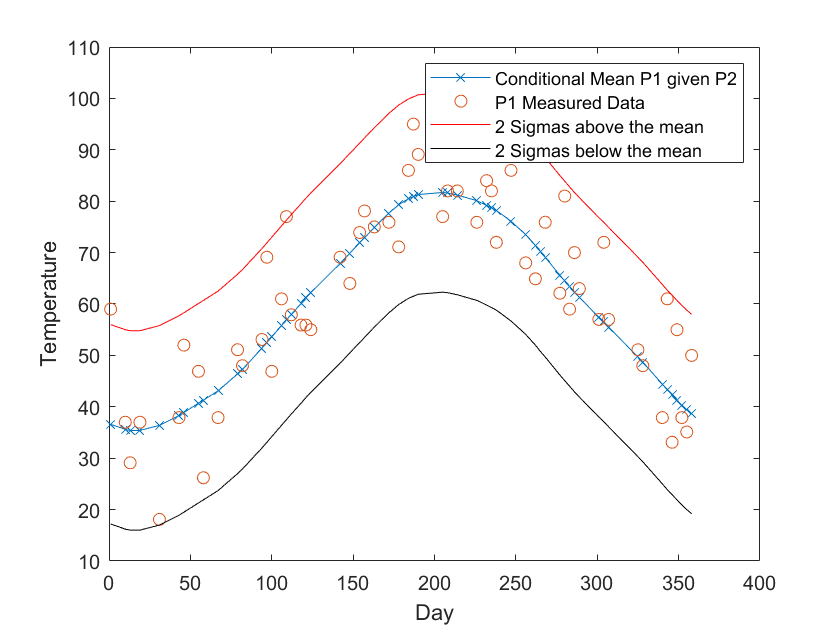

figure;
plot(k1_x2,mu_1_2,'-x')
hold on
plot(k1_x2,data(k1_x2,1),'o')
xlabel('Day');
ylabel('Temperature');

plot(k1_x2,mu_1_2+2*(diag(sigma_1_2)),'-r');
plot(k1_x2,mu_1_2-2*(diag(sigma_1_2)),'-k');
legend('Conditional Mean P1 given P2','P1 Measured Data','2 Sigmas above the mean', '2 Sigmas below the mean');
hold off

## A Plot of the Conditional Distributions

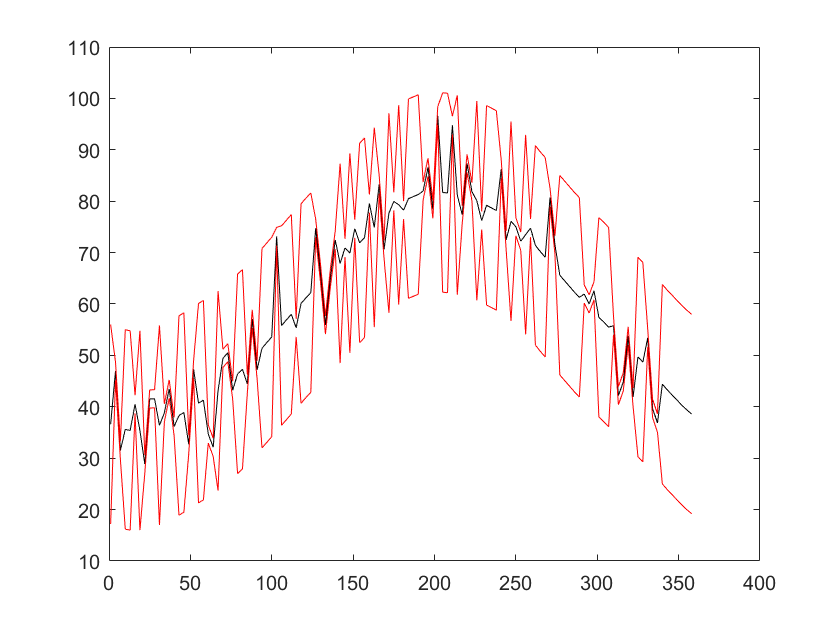

figure;
new_mu(k1_x2) = mu_1_2;
new_mu(k2_x2) = mu_2_2;

new_sigma(k1_x2) = diag(sigma_1_2);
new_sigma(k2_x2) = diag(sigma_2_2);

plot(ind_x2,new_mu(1:3:end),'k');
hold on
plot(ind_x2,new_mu(1:3:end)+2*new_sigma(1:3:end),'r');
plot(ind_x2,new_mu(1:3:end)-2*new_sigma(1:3:end),'r');

### Evaluating the Performance

Once the conditional mean and conditional variance have been computed for a particular set of parameters, the next step is to evaluate the performance of those parameters. Again, there is several options once can choose from as a merit function for the parameter selected.

Let's select as merit function the log marginal likelihood. In this case, a set of parameters that generate larger values, will indicate better peformance.

We define the log marginal likelihood of the partition $X_2^i$ given $X_2^{-i}$ as


$$\log p\left( \mathbf{X}_2^{i} \mid \mathbf{X}_2^{-i},\theta    \right)  \\
        = \log \left( \frac{1}{(2\pi)^{((N-d)/k)/2} |\Sigma_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}}  |^{1/2}} \exp \left(-\frac{1}{2}( \mathbf{X}_2^{i}-\mathbf{\mu}_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}} )^T\Sigma_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}} ^{-1}( \mathbf{X}_2^{i}-\mathbf{\mu}_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}} )\right) \right)\\
    = -\log \left( (2\pi)^{((N-d)/k)/2} |\Sigma_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}} |^{1/2} \right) -\frac{1}{2}(\mathbf{X}_2^{i}-\mathbf{\mu}_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}})^T\Sigma^{-1}(\mathbf{X}_2^{i}-\mathbf{\mu}_{\mathbf{X}_2^{i}|\mathbf{X}_2^{-i}}),$$


Thus, the total merit can be computed as the summation for each of the partition $i$ as


$$  \sum_{i=1}^k  \log p\left( \mathbf{X}_2^{i} \mid \mathbf{X}_2^{-i},\theta    \right).$$


Formally, the optimization problem to be solved in order to find a "good" set of parameters is


$$\max_\theta  \sum_{i=1}^k  \log p\left( \mathbf{X}_2^{i} \mid \mathbf{X}_2^{-i},\theta    \right).$$


## A running example for finding a "good" set of parameters

Initially, we need to set the search space

#### Define Search Space

We have defined the set of parameters for the selected kernel function $\theta =\left(a,\ell \right)$ in this particular recitation, we will follow a brute force approach where we are going to test the performance of a number of values and select the one with the better performance.There are more sophisticated ways to select the parameter, such as gradient-based approaches. Feel free to explore those in your homework!

For simplicity, we are going to explore

a_vals = [70:0.1:90];
ell_vals = [2:0.01:4];

Now lets see how this works

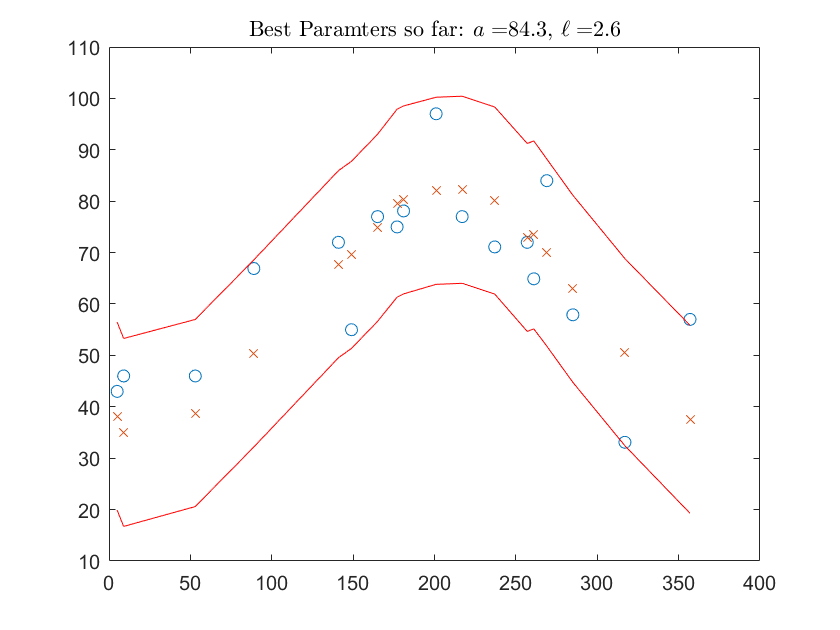

clc                                    % Clear memory
clear all                              % Clear memory

d = load('data.mat');               % Load the data
data = d.data;                      % Extract the data

ind_x2 = [1:4:360];                % Find the indices of the measured data
indx = zeros(360,1);
indx(ind_x2) = ind_x2;             

K=5;    % Set number of partitions
perm_ex = randperm(size(ind_x2,2));

% Build the indices for each of the permulations
c=1;
while isempty(perm_ex)==0
    partition{c} = ind_x2(perm_ex(1:ceil(size(ind_x2,2)/K)));
    perm_ex(1:ceil(size(ind_x2,2)/K)) = [];
    c = c+1;
end

%% Compute the Covariance Matrix using the Kernel function
covs = repmat([1:365],365,1) - repmat([1:365]',1,365);
c1=1;
c2=1;

ymax = -inf;    % Auxiliary variable for storing the best cost function value

% Safe the means 



for i=80:0.1:90               % For loop for one parameters
    for j=2:0.1:4           % For loop for the other parameter
            sigma = i*exp( -covs.^2 / (j^2));     % Computing the covariance matrix with 
                                                   %   the selected parameters
            
            for k=1:K           % For loop for the number of partitions
                x_test = sort(partition{k});
                copy_indx = indx;
                copy_indx(partition{k}) = [];
                copy_indx(copy_indx==0) = [];
                x_train = copy_indx';
                
                mu_1 = data(x_test,3);
                mu_2 = data(x_train,3);
                
                % Separate the components of the Covariance function
                sigma_11 = sigma(x_test,x_test);
                sigma_12 = sigma(x_test,x_train);
                sigma_21 = sigma(x_train,x_test);
                sigma_22 = sigma(x_train,x_train);

                % Compute Conditional distribution parameters
                mu_1_2 = mu_1 + sigma_12*((sigma_22+1*eye(size(mu_2,1)))\(data(x_train,1)-mu_2));
                sigma_1_2 = sigma_11 - sigma_12*((sigma_22+1*eye(size(mu_2,1)))\sigma_12');

                % Compute the performance of the current partiion on the
                % test data
                val(k) = logmvnpdf(data(x_test,1)',mu_1_2',sigma_1_2);
                
                
                
            end
            % Compute the total peformance for all the partitions
            tot(c1,c2) = sum(val);
            
            % Update the values for the best performance function
            if tot(c1,c2) > ymax
                imax = i;
                jmax = j;
                ymax = tot(c1,c2);
            
                plot(x_test,data(x_test,1),'o')
                hold on
            %     plot(test,mu_test_new,'o')
                plot(x_test,mu_1_2,'x')
                plot(x_test,mu_1_2+2*sqrt(diag(sigma_1_2)),'r')
                plot(x_test,mu_1_2-2*sqrt(diag(sigma_1_2)),'r')
                hold off
                title(strcat('Best Paramters so far: $a=$',num2str(imax),', $\ell=$',num2str(jmax)), 'interpreter', 'latex')
                drawnow
            end
            c1=c1+1;
    end
            c1=1;
            c2=c2+1;
end


% Compute the Covariance matrix with the best set of parameters
sigma_opt = imax*exp( -covs.^2 / (jmax^2));


Recall that we have chosen the kernel function:


$$k\left(z_1 ,z_2 \right)=a*\exp \left(-\frac{\left\|z_1 -z_2 {\left\|\right.}^2 \right.}{2\ell^2 }\right)\ldotp$$


## Generating an estimate for the unobserved random variables.

Now that we have a set of "good" parameters for our kernel function, we can generate an estimate for the unobserved temperatures.

First we separate the components of the Covariance matrix witht the optimal parameters.

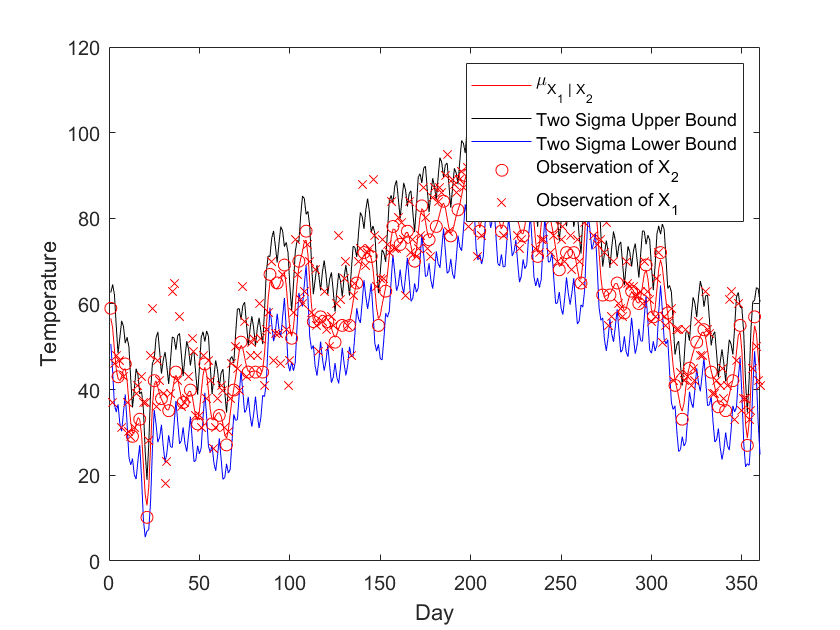

ind_x2 = [1:4:360];
ind_x1 = [1:360];
ind_x1(ind_x2)=[];

%% First  separate the components of the covariance matrix
sigma_11_n = sigma_opt(ind_x1,ind_x1);
sigma_12_n = sigma_opt(ind_x1,ind_x2);
sigma_21_n = sigma_opt(ind_x2,ind_x1);
sigma_22_n = sigma_opt(ind_x2,ind_x2);

mu_x1 = data(ind_x1,3);
mu_x2 = data(ind_x2,3);

mu_x1_n = mu_x1 + sigma_12_n*((sigma_22_n+10*eye(size(mu_x2,1)))\(data(ind_x2,1)-mu_x2));
sigma_x1_n = sigma_11_n - sigma_12_n*((sigma_22_n+10*eye(size(mu_x2,1)))\sigma_12_n');

mu_x2_n = mu_x2 + sigma_22_n*((sigma_22_n+10*eye(size(mu_x2,1)))\(data(ind_x2,1)-mu_x2));
sigma_x2_n = sigma_22_n - sigma_22_n*((sigma_22_n+10*eye(size(mu_x2,1)))\sigma_22_n');

new_mu(ind_x1)=mu_x1_n;
new_mu(ind_x2)=mu_x2_n;

new_sigma(ind_x1) = diag(sigma_x1_n);
new_sigma(ind_x2) = diag(sigma_x2_n);

figure;
plot(new_mu,'r')
hold on
plot(new_mu+2*sqrt(new_sigma),'-k')
plot(new_mu-2*sqrt(new_sigma),'-b')
plot(ind_x2,data(ind_x2,1),'or')
plot(ind_x1,data(ind_x1,1),'xr')
xlim([0,360])
xlabel('Day');
ylabel('Temperature');
legend('\mu_{X_1 | X_2 }','Two Sigma Upper Bound','Two Sigma Lower Bound','Observation of X_2', 'Observation of X_1');
hold off